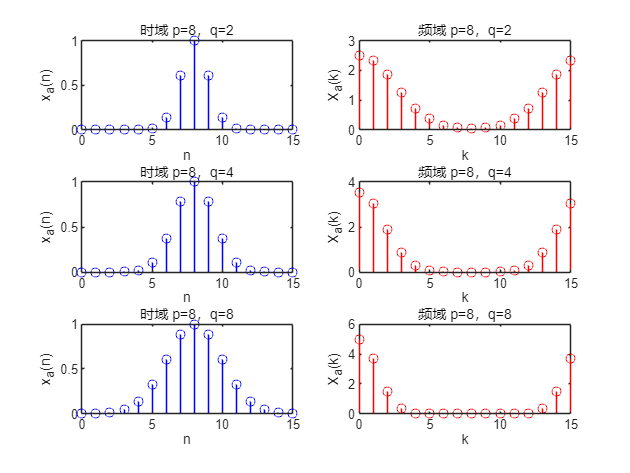

%%固定p=8,改变q
figure;
p=8;
q=[2,4,8];
n=0:15;
for i=1:length(q)
    xa=exp(-(n-p).^2/q(i));
    subplot(3,2,2*i-1);
    stem(n,xa,'b');
    title(['时域 p=8，q=',num2str(q(i))]);xlabel('n');ylabel('x_a(n)');
    subplot(3,2,2*i);
    y=fft(xa);
    stem(n,abs(y),'r');title(['频域 p=8，q=',num2str(q(i))]);xlabel('k');ylabel('X_a(k)');
end

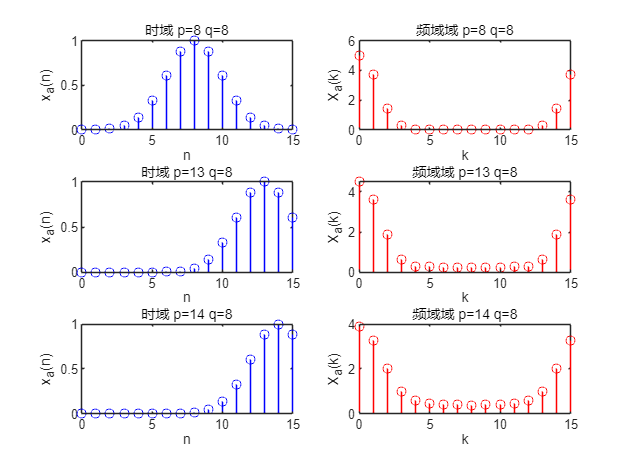


%%固定q=8,改变p
figure;
q=8;
p=[8,13,14];
n=0:15;
for i=1:length(p)
    xa=exp(-(n-p(i)).^2/q);
    subplot(3,2,2*i-1);
    stem(n,xa,'b');title(['时域 p=',num2str(p(i)),' q=8']);
    xlabel('n');ylabel('x_a(n)');
    subplot(3,2,2*i);
    z=fft(xa);
    stem(n,abs(z),'r');title(['频域域 p=',num2str(p(i)),' q=8']);
    xlabel('k');ylabel('X_a(k)');
end

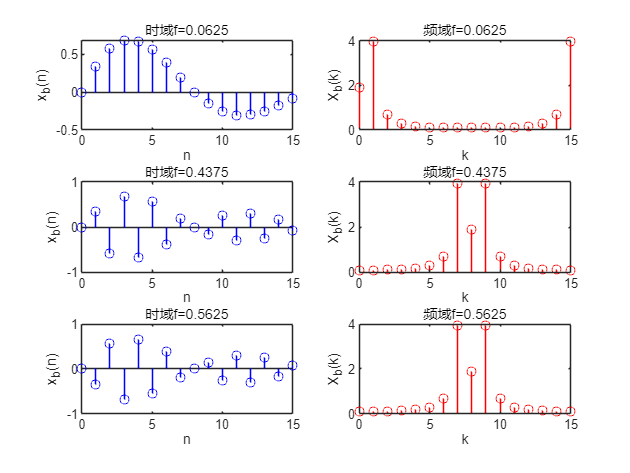

figure;
a=0.1;
f=[0.0625,0.4375,0.5625];
n=0:15;
for i=1:length(f)
    xb=exp(-a*n).*sin(2*pi*f(i)*n);
    subplot(3,2,2*i-1);
    stem(n,xb,'b');title(['时域f=',num2str(f(i))]);
    xlabel('n');ylabel('x_b(n)');
    subplot(3,2,2*i);
    xb_f=fft(xb);
    stem(n,abs(xb_f),'r');title(['频域f=',num2str(f(i))]);
    xlabel('k');ylabel('X_b(k)'); 
end

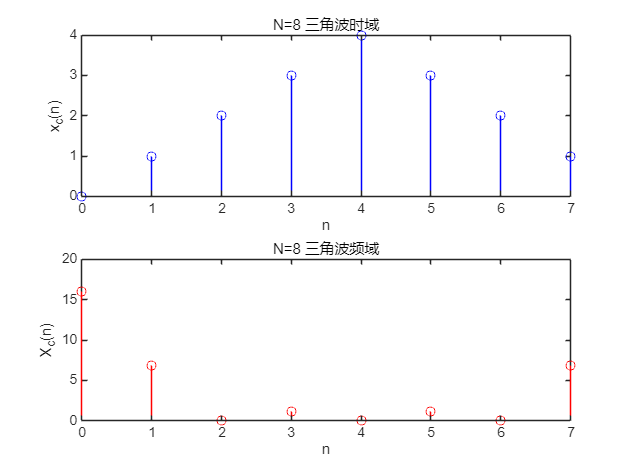


%三角波序列函数
function xc=xc_n(n)
for i = 1:length(n)
    if n(i) >= 0 && n(i) <= 3
        xc(i) = n(i);
    elseif n(i) >= 4 && n(i) <= 7
        xc(i) = 8 - n(i);
    elseif 7<n(i)<=n(length(n))
        xc(i)=0;
    end
end
end

%反三角波序列函数
function xd=xd_n(n)
for i=1:length(n)
    if n(i)>=0&&n(i)<=3
        xd(i)=4-n(i);
    elseif n(i)>=4&&n(i)<=7
        xd(i)=n(i)-4;
    elseif 7<n(i)<=n(length(n))
        xd(i)=0;
    end

end
end


figure;
n=0:7;
xc=xc_n(n);
subplot(2,1,1);
stem(n,xc,'b');
xlabel('n');
ylabel('x_c(n)');
title('N=8 三角波时域');
subplot(2,1,2);
xc_f=fft(xc);
stem(n,abs(xc_f),'r');
xlabel('n');
ylabel('X_c(n)');
title('N=8 三角波频域');

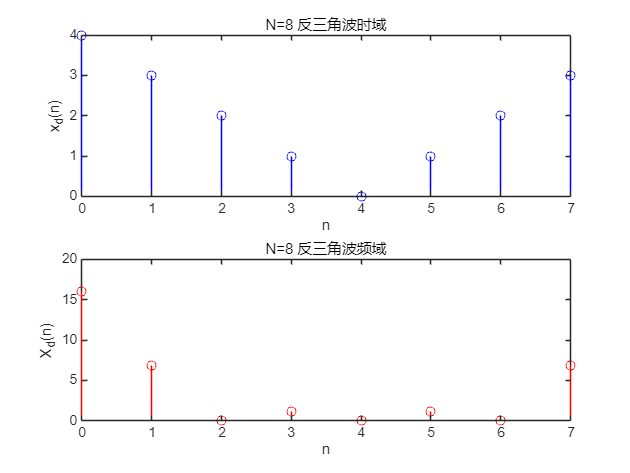


figure;
n=0:7;
xd=xd_n(n);
subplot(2,1,1);
stem(n,xd,'b');
xlabel('n');
ylabel('x_d(n)');
title('N=8 反三角波时域');
subplot(2,1,2);
xc_f=fft(xd);
stem(n,abs(xc_f),'r');
xlabel('n');
ylabel('X_d(n)');
title('N=8 反三角波频域');

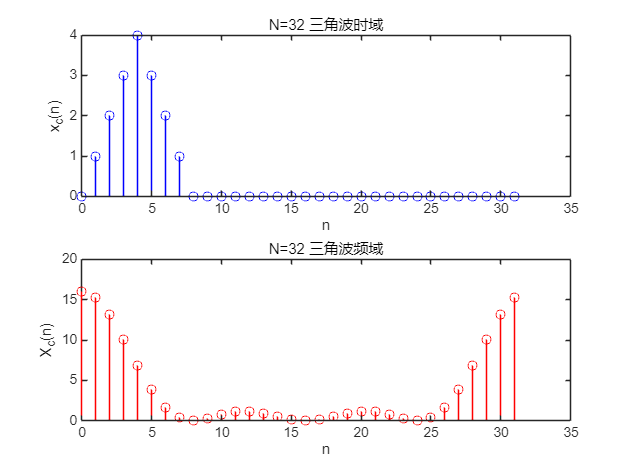

n=0:31;
figure;
xc=xc_n(n);
subplot(2,1,1);
stem(n,xc,'b');
xlabel('n');
ylabel('x_c(n)');
title('N=32 三角波时域');
subplot(2,1,2);
xc_f=fft(xc);
stem(n,abs(xc_f),'r');
xlabel('n');
ylabel('X_c(n)');
title('N=32 三角波频域');

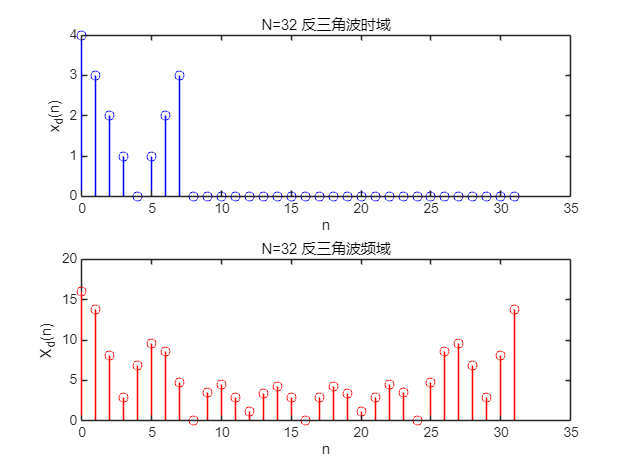

figure;
n=0:31;
xd=xd_n(n);
subplot(2,1,1);
stem(n,xd,'b');
xlabel('n');
ylabel('x_d(n)');
title('N=32 反三角波时域');
subplot(2,1,2);
xc_f=fft(xd);
stem(n,abs(xc_f),'r');
xlabel('n');
ylabel('X_d(n)');
title('N=32 反三角波频域');

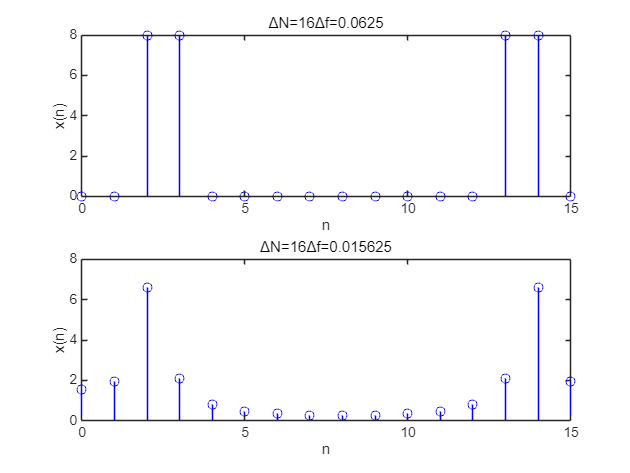


delt_f=[1/16,1/64];
n=0:15;
m=0:127;
function x_nf(n,delt_f,k)
figure;
for i=1:length(delt_f)
    xn=sin(2*pi*0.125*n)+cos(2*pi*(0.125+delt_f(i))*n);
    xn_f=fft(xn);subplot(2,1,i+k);
    stem(n,abs(xn_f),'b');xlabel('n');ylabel('x(n)');
    title(['\DeltaN=',num2str(length(n)),'\Deltaf=',num2str(delt_f(i))]);
end

end

%----N=16,△f=1/16和1/64---%
x_nf(n,delt_f,0);

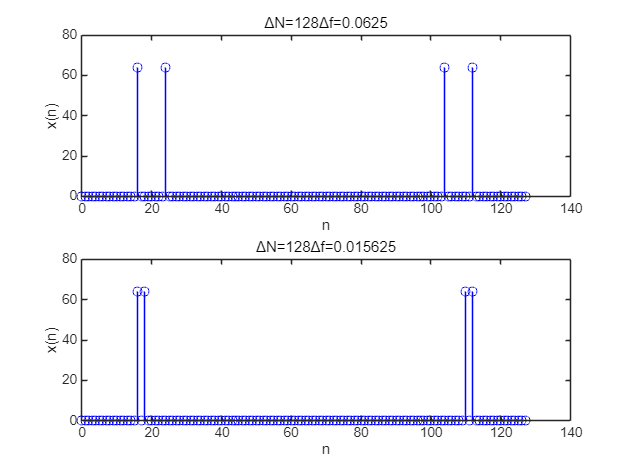

%----N=128,△f=1/16和1/64---%

x_nf(m,delt_f,0);

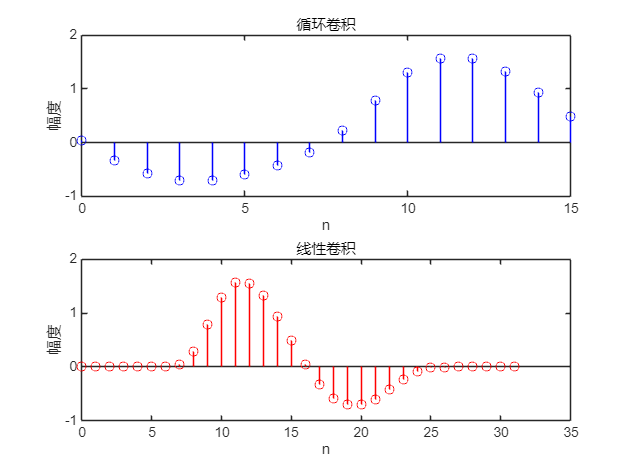

figure;

%---用FFT表示循环卷积---%
n=0:15;
xa_n=exp(-(n-8).^2/2);
xb_n=exp(-0.1*n).*sin(2*pi*0.0625*n);
z_n=fft(xa_n).*fft(xb_n);
w_n=ifft(z_n);
subplot(2,1,1);
stem(n,w_n,'b');
xlabel('n');
ylabel('幅度');
title('循环卷积');

%---用FFT表示线性卷积---%
%xa,xb后增加N个零点
n2=0:31;
xa_n2=exp(-(n2-8).^2/2).*(n2>=0&n2<=15);
xb_n2=exp(-0.1*n2).*sin(2*pi*0.0625*n2).*(n2>=0&n2<=15);   
z_n2=fft(xa_n2).*fft(xb_n2);
w_n2=ifft(z_n2);
subplot(2,1,2);
stem(n2,w_n2,'r');
xlabel('n');
ylabel('幅度');
title('线性卷积');

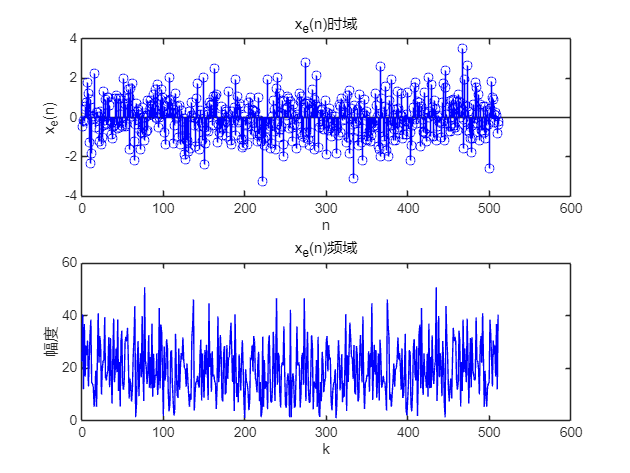

xe=randn(1,512);
figure;
subplot(2,1,1);
stem(xe,'b');
xlabel('n');
ylabel('x_e(n)');
title('x_e(n)时域');
subplot(2,1,2);
xe_f=fft(xe);
plot(0:512-1,abs(xe_f),'b');
xlabel('k');
ylabel('幅度');
title('x_e(n)频域');

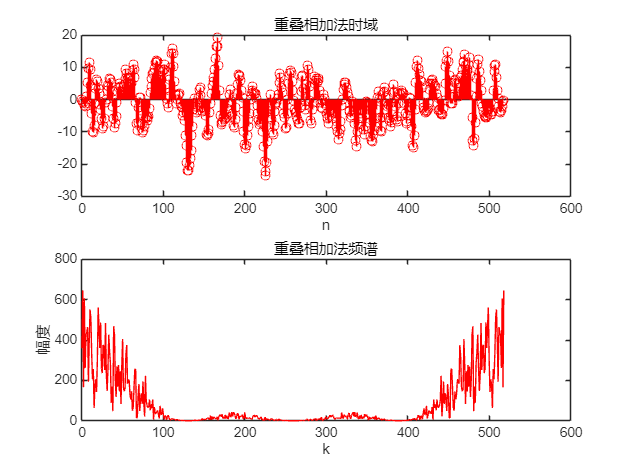

%d对每段xe后补零
n2=0:7;
xc=xc_n(n2);
set=8;
y=zeros(1,length(xe)+length(n2)-1);
L=length(xe)/set+length(n2)-1;%重叠相加法，补n-1个0后的长度
for i=0:set-1
    xe_part=xe((64*i+1):(64*(i+1)));
    xe_part_f=fft(xc,L).*fft(xe_part,L);
    y_part=ifft(xe_part_f,L);
    y((64*i+1):(64*i+64+8-1))=y((64*i+1):(64*i+64+8-1))+y_part;
end
figure;
subplot(2,1,1);
stem(0:length(y)-1,y,'r');
xlabel('n');title('重叠相加法时域');
y_f=fft(y);
subplot(2,1,2);
plot(0:length(y)-1,abs(y_f),'r');
xlabel('k');
ylabel('幅度');
title('重叠相加法频谱');

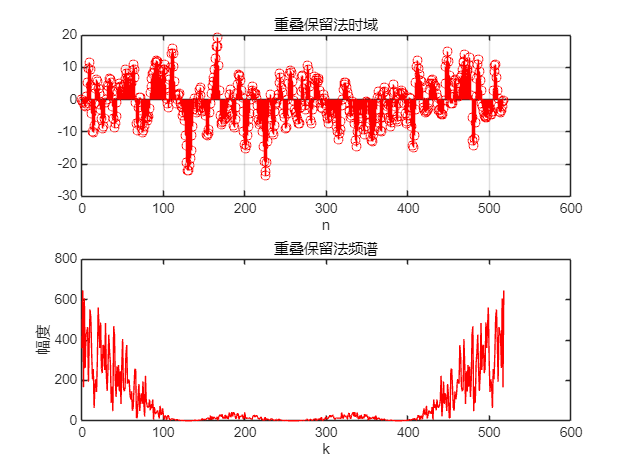

%xe每段前保留上一段的length(n)-1个数据

xe_2=[zeros(1,7),xe,zeros(1,64)];%前面增加n-1个数据点，后面增加一段全零样本
y2=zeros(1,(set+1)*length(xe)/set);
for i=0:set
        xe_part2=xe_2((64*i+1):(64*(i+1)+8-1));
        xe_part2_f=fft(xc,L).*fft(xe_part2,L);
        y_part2=ifft(xe_part2_f,L);
        y2((64*i+1):(64*i+64))=y2((64*i+1):(64*i+64))+y_part2(8:L);
end
y_result=y2(1:length(xe)+length(n2)-1);
figure;
subplot(2,1,1);
stem(0:length(y_result)-1,y_result,'r');
xlabel('n');title('重叠保留法时域');
y_result_f=fft(y_result);grid on;
subplot(2,1,2);
plot(0:length(y_result)-1,abs(y_result_f),'r');
xlabel('k');
ylabel('幅度');
title('重叠保留法频谱');

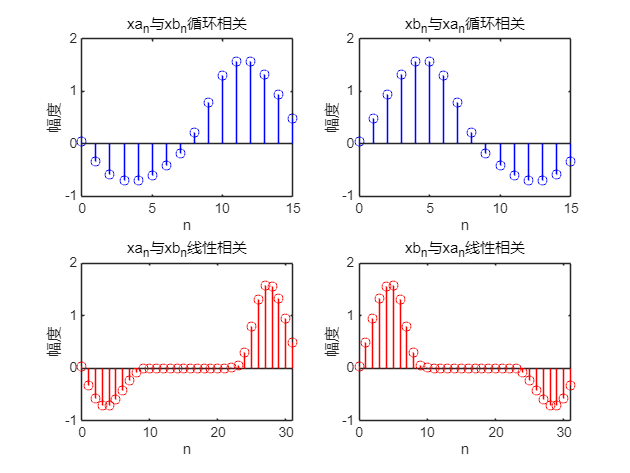

%xa_n与xb_n循环相关
n=0:15;
xa_n=exp(-(n-8).^2/2);
xb_n=exp(-0.1*n).*sin(2*pi*0.0625*n);
z_n=conj(fft(xa_n)).*fft(xb_n);
w_n=ifft(z_n);
figure;
subplot(2,2,1);
stem(n,w_n,'b');
xlabel('n');
ylabel('幅度');
title('xa_n与xb_n循环相关');

%xb_n与xa_n循环相关
n=0:15;
xa_n=exp(-(n-8).^2/2);
xb_n=exp(-0.1*n).*sin(2*pi*0.0625*n);
z_n=conj(fft(xb_n)).*fft(xa_n);
w_n=ifft(z_n);
subplot(2,2,2);
stem(n,w_n,'b');
xlabel('n');
ylabel('幅度');
title('xb_n与xa_n循环相关');
%xa_n与xb_n线性相关
n2=0:31;
xa_n2=exp(-(n2-8).^2/2).*(n2>=0&n2<=15);
xb_n2=exp(-0.1*n2).*sin(2*pi*0.0625*n2).*(n2>=0&n2<=15);   
z_n2=conj(fft(xa_n2)).*fft(xb_n2);
w_n2=ifft(z_n2);
subplot(2,2,3);
stem(n2,w_n2,'r');
xlabel('n');
ylabel('幅度');
title('xa_n与xb_n线性相关');

%xb_n与xa_n线性相关
n2=0:31;
xa_n2=exp(-(n2-8).^2/2).*(n2>=0&n2<=15);
xb_n2=exp(-0.1*n2).*sin(2*pi*0.0625*n2).*(n2>=0&n2<=15);   

z_n2=conj(fft(xb_n2)).*fft(xa_n2);
w_n2=ifft(z_n2);
subplot(2,2,4);
stem(n2,w_n2,'r');
xlabel('n');
ylabel('幅度');
title('xb_n与xa_n线性相关');

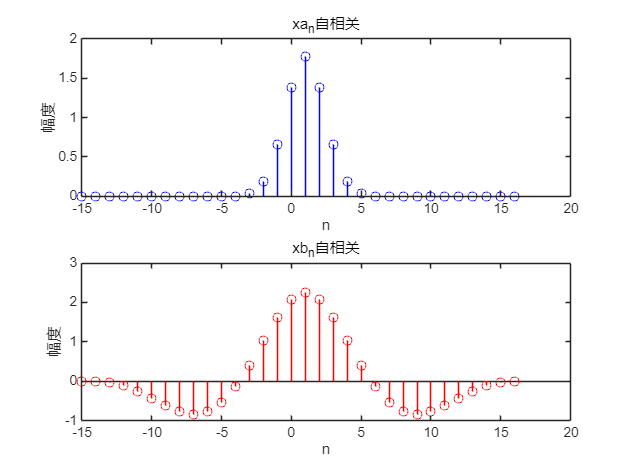


figure;
%xa_n自相关
k=16;
n2=0:31;
xa_n2=exp(-(n2-8).^2/2).*(n2>=0&n2<=15);
xb_n2=exp(-0.1*n2).*sin(2*pi*0.0625*n2).*(n2>=0&n2<=15);   
n2=(-k+1):(k);
z_n2=conj(fft(xa_n2)).*fft(xa_n2);
w_n2=ifft(z_n2);
w_n2=[w_n2(k+1:2*k),w_n2(1:k)];
subplot(2,1,1);
stem(n2,w_n2,'b');
xlabel('n');
ylabel('幅度');
title('xa_n自相关');

%xa_n自相关
z_n2=conj(fft(xb_n2)).*fft(xb_n2);
w_n2=ifft(z_n2);
w_n2=[w_n2(k+1:2*k),w_n2(1:k)];
subplot(2,1,2);
stem(n2,w_n2,'r');
xlabel('n');
ylabel('幅度');
title('xb_n自相关');